syms y(t) 
ode= diff(y,t,2) +3*diff(y,t) +2*y == 5

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=5$$

Du=diff(y,t);
cond1 = y(0) == 1;
cond2 = Du(0) == 1;
conds = [cond1 cond2];
ySolv(t)=dsolve(ode,conds)

$$ySolv(t) = \frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

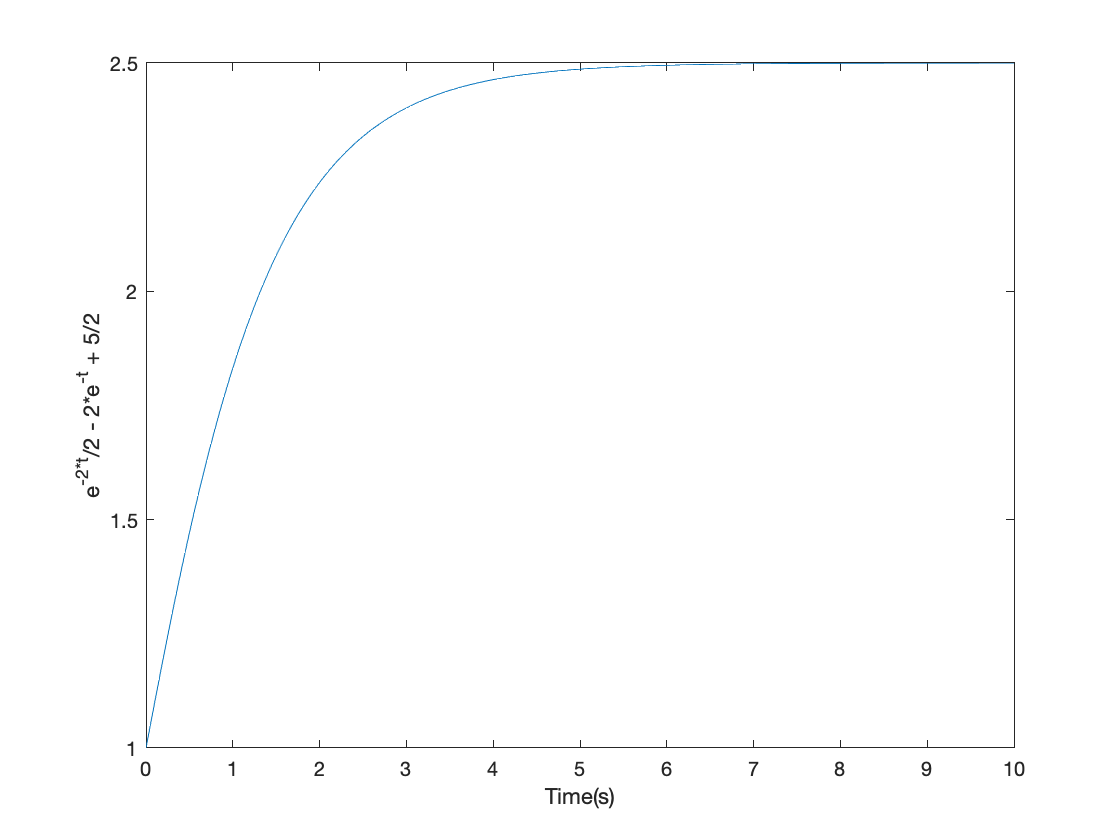

T=0:1/20:10;
Final=subs(ySolv,t,T);
plot(T,Final)
xlabel 'Time(s)'
ylabel 'e^{-2*t}/2 - 2*e^{-t} + 5/2'